# Simulating Stochastic Dynamics of Gene Expression

Gene expression, the transmission of information from nucleic acids to  proteins, involves a series of biochemical reactions occurring randomly within living cells. This randomness arises due to the varying abundance of specific proteins among genetically identical cells growing in the same environment.

The following is a theoretical model that describes the inherently noisy translation and transcription mechanism. To do so, we developed the following set of equations:

$R^{\prime}=r -\alpha R\\
P^{\prime}=kR-\beta P\\$                                                                    (1)

where, $R$ and $P$ represents the number of RNAs and proteins. $r$ and $\alpha$ is the rate of transcription and degredation of RNA, whereas $k$ and $\beta$ is the rate of protein translation and degradation. 

 At steady state:

$R^{\star}=\frac{r}{\alpha}\\
P^{\star}=k\frac{R^{\star}}{\beta}=\frac{kr}{\alpha\beta}
$                                                                    (2)

### Simulation of the Model

#### Discrete time Monte-carlo method

Let's assume $k$ represents some reaction rate of a system at time $t$ . Let us denote $f(\tau )d\tau$ to be the probability of the next reaction occurring in the time interval $[t+\tau,t+\tau +d\tau )$ where $d\tau$ is an infinitesimally small time step. In order for this to happen, there must be no reaction in the interval $[t,t+\tau )$ and then a reaction in the interval $[t+\tau,t+\tau +d\tau )$ . If we assume $g(\tau )$ represents the probability of no reaction occurring in the interval $[t,t+\tau$). Then $f(\tau )d\tau$ can be calculated as:

$f(\tau )d\tau =g(\tau )\times kd\tau $                                                                                    (3)

$kd\tau$ is the probability of a reaction occurring in the interval $[t+\tau,t+\tau +d\tau )$ . For any $\tau >0$, the probability that no reaction occurs in the interval  $[t,t+\tau +d\tau )$ can be calculated by multiplying the probability of no reaction in the interval $[t,t+\tau  )$ and the probability of no reaction in the interval $[t+\tau,t+\tau +d\tau )$. Hence:

$g(\tau +d\tau )=g(\tau )\times (1-kd\tau )$                                                                       (4)

Now, rearranging Equation 4  :

$\frac{g(\tau +d\tau )-g(\tau )}{d\tau }=-kg(\tau )$                                                                         (5)

Now in the limit $d\tau\rightarrow 0$, we obtain the following ODE:

$\frac{dg(\tau )}{d\tau }=-kg(\tau )$                                                                                          (6)

Solving this equation using $g(0)=1$, we get:

$g(\tau )=e^{-k\tau }$                                                                                                (7)

Now we can write Equation 3 as:

$f(\tau )d\tau =k e^{-k\tau} d\tau $                                                                                       (8)

Now, say $N$ reactions with rates $k_1, k_2, \ldots k_N$ happend at time $t_1, t_2, \ldots t_N$, then the probability that none of the reactions happened before $\tau$ is (using Eq 7):

$g(t_1>\tau) g(t_2>\tau) \ldots g(t_N>\tau)=\prod_{i=1}^{N} e^{-k_i\tau}=e^{-\tau \sum_{i=1}^{N} k_i}$                                                                                (9)

We will use these general principles to simulate our model.

To simulate our model we will implement discrete time step Monte-Carlo method first. Because this is the simplest algorithm to implement. In this method, the total simulation time is divided into small time steps $\Delta t$

**Initialization**:

The initial value of RNA is R0 (R=R0) and protein is P0 (P=P0).

After initialization do the following at each time step:

(1) Calculate the total reaction rate $$k_0=r+\alpha R+kR+\beta P$ and the calculate the total reaction probility   $\mathbb P_{reaction}=1-e^{-k_0 \Delta t$

(2) Generate a uniform random number  $\mathbb R_1 \in[0,1]$ and compare the reaction probability $\mathbb P_{reaction}$ with $\mathbb R_1$. If $\mathbb R_1<\mathbb P_{reaction}$ a reaction will happen, otherwise store the previous values of RNA and protein number in the current state.

(3) If a reaction occurs, we have to choose which reaction to execute. To do so, generate another uniform random number $\mathbb R_2 \in[0,1]$ find $j$ such that:


$$\mathbb R_2>=\frac{1}{k_0}\sum_{i=1}^{j-1} k_i (t)~~\&~~\mathbb R_2<\frac{1}{k_0}\sum_{i=1}^{j} k_i(t)$$


(4) Update the chosen reaction by inceasing or decreasing the copy number by 1.  

(5) Continue these step until the simulation end time.

**Note on choosing **$\Delta t$**:**

This method is computationally expensive because it iterates over every time step to update reactions. Additionally, the choice of the time step ($\Delta t$) is crucial, needs to be much smaller than the average time between reactions ($$1/\sum_{i} k_i$$). A smaller $\Delta t$ leads to more iterations, and since $\Delta t$ is proportional to the reaction probability, small $\Delta t$ results in many time steps where no reaction occurs. $\Delta t$ need to be chosen so that it is much smaller than the largest expected rate. A good strategy is to calculate the sum of the rates at initail and final values and choose $\Delta t$ accordingly so that the probability of a reaction is less 0.1. After completing the simulation, check that decreasing $\Delta t$ by 10-fold doesn't change the results. 

**Execution of the algorithm:**

An simple execution of this algorithm to simulate the transcription and translation process as described by our model is shown in the function named 'RNAProtein_MonteCarlo' at the bottom of this writeup. The protein number/concentration coming out of this process can be approximated using a gamma distribution (see Taniguchi et al., Science & Friedman et al., PRL) with two parameters $a$ and $b$. $a$ being the number of bursts per protein lifetime and $b$ being the mean number of proteins translated per burst.  For $a$<=1 the gamma distribution become an exponential distribution. We can adjust the paramets to make a<1 and then simulate our model.  Here is the code:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% case 1; 
p.alpha=0.01;%%/s, RNA degredation rate
p.beta=0.003;%%/s, Protein degradation rate
p.r=0.001; %RNA production rate 
p.k=0.1;%%/s, Protein Synthesis rate 
p.a=p.r/p.beta;%%%% number of bursts per protein lifetime
p.b=p.k/p.alpha;%%%% number of protein in each burst

%Now simulate using monte carlo
p.startTime = 0;%% simulation start time
p.endTime =  60*100; % in seconds
p.nrep = 500;  % number of replicate simulations
p.dt=0.1;%%time step

%%%%%initilaization
R0=0;%%% initial value of number of RNA 
P0=0;%%% initial value of number of RNA 
%%%Run the stochastic simulation
[T1,R1,P1]=RNAProtein_MonteCarlo(p,R0,P0);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Now lets plot the number of RNA and protein as a function of time:

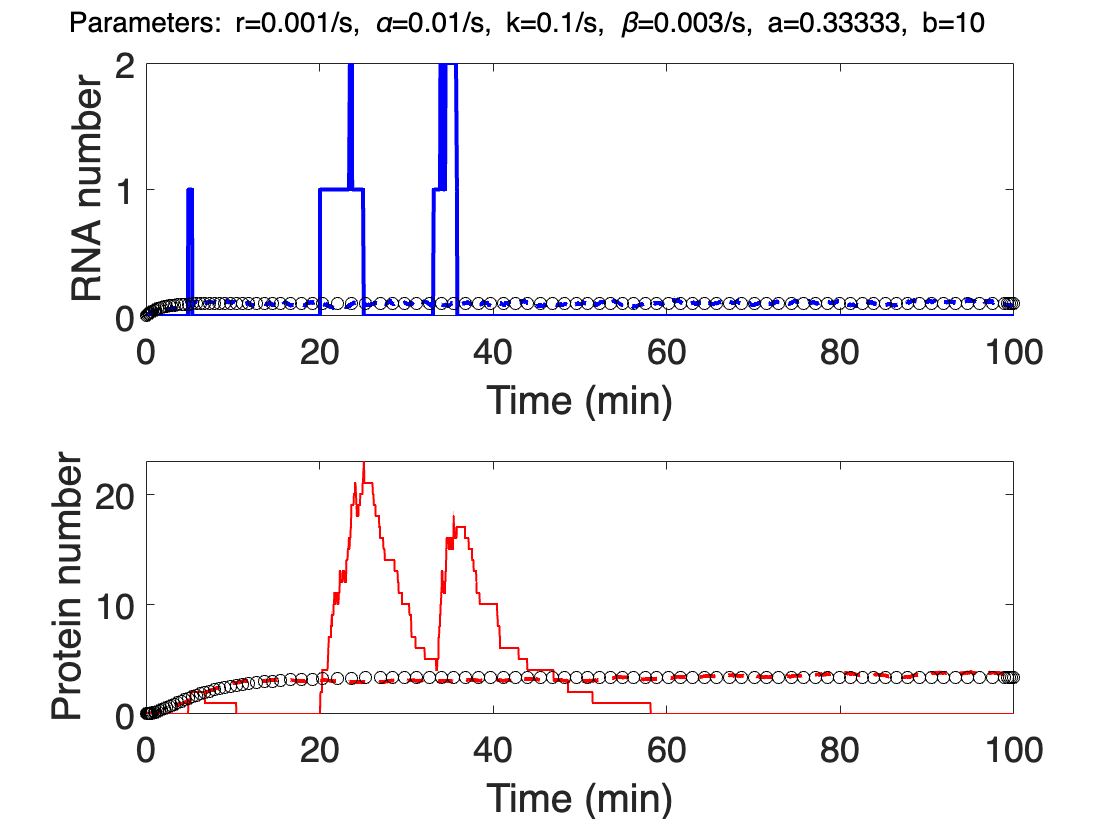

plot_trace(p,T1,R1,P1)

The result clearly shows the protein bursts are infrequent and the proteins before another burst happens. Now, we can look at the statistics and plot the distribution of proteins:

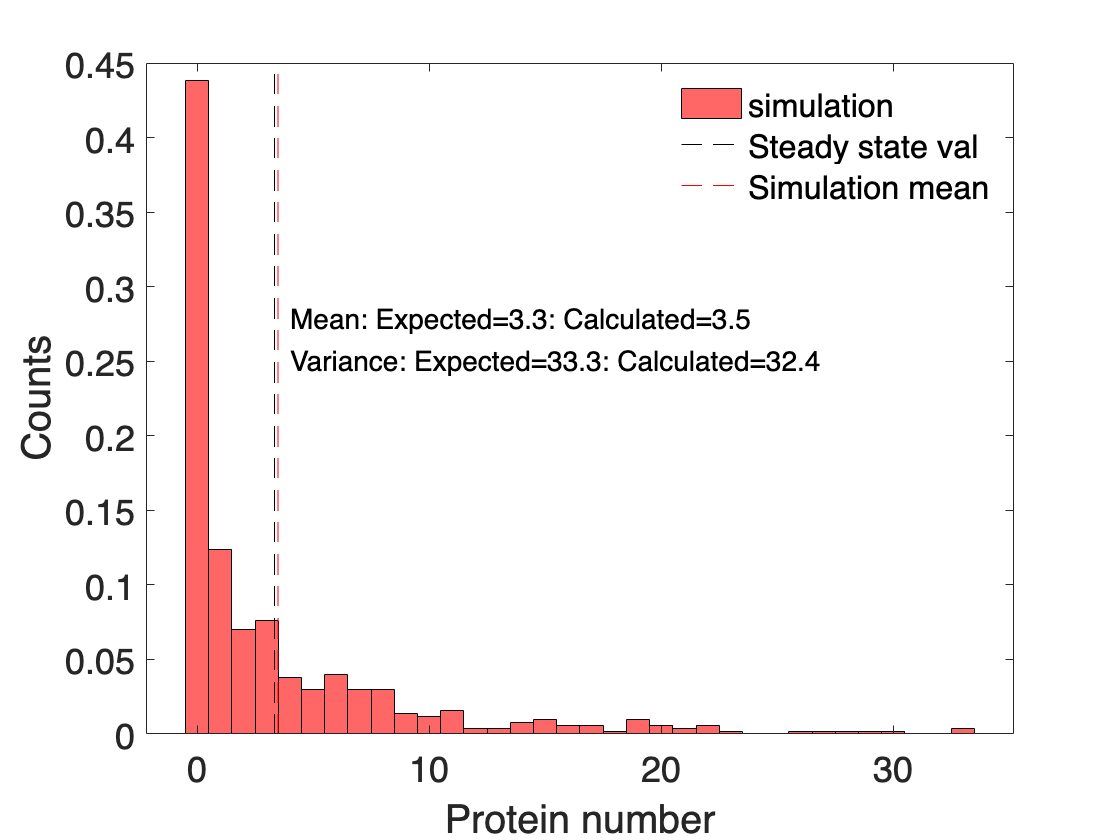

plot_statistics(p,P1)	

[P1_mean_cal, P1_mean_expec, P1_var_cal, P1_var_expec] = display_statistics(p, P1);

Variance: Expected=33.3333\n: Calculated=32.3986\nMean: Expected=3.3333\n: Calculated=3.486\nCV: Expected=1.7321\n: Calculated=1.6328

Now lets change the number of protein bursts per lifetime $a$ to be exactly 1  and run the simulation again: 

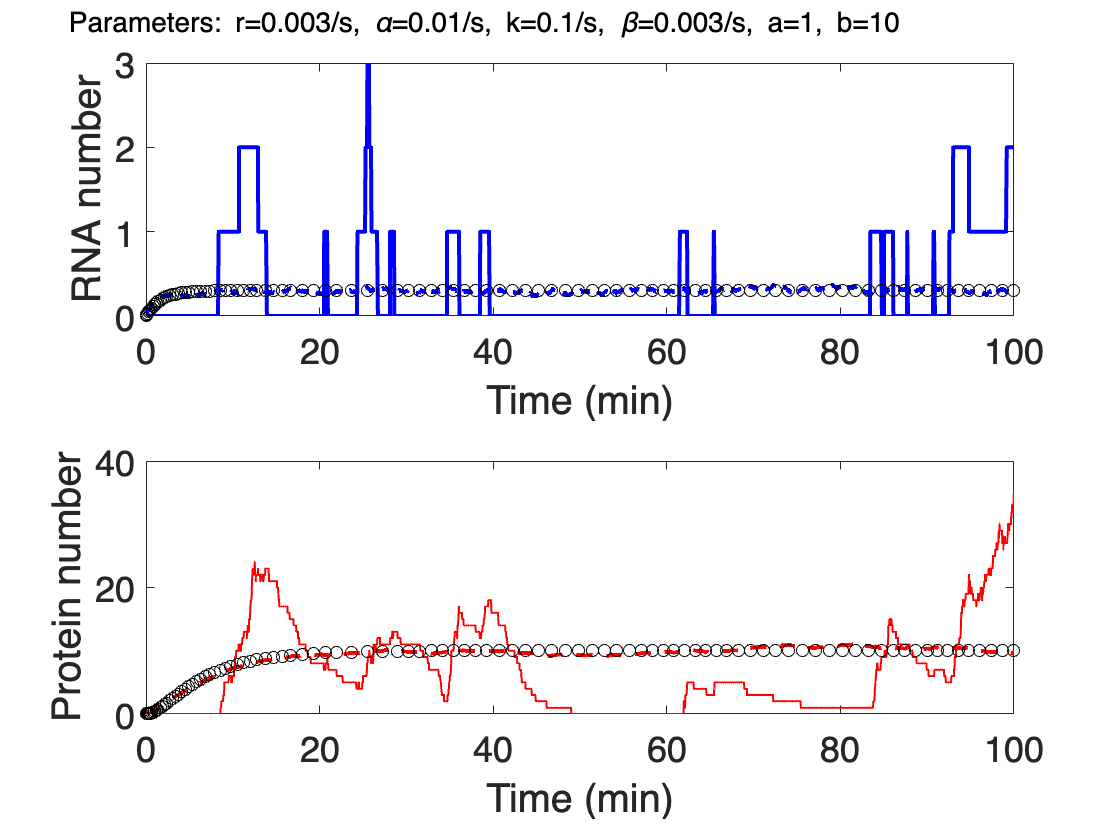

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% case 2
p.alpha=0.01;%%/s, RNA degredation rate
p.beta=0.003;%%/s, Protein degradation rate
p.r=0.003; %RNA production rate 
p.k=0.1;%%/s, Protein Synthesis rate 
p.a=p.r/p.beta;%%%% number of bursts per protein lifetime
p.b=p.k/p.alpha;%%%% number of protein in each burst

%Now simulate using monte carlo
p.startTime = 0;
p.endTime =  60*100; % in seconds
p.nrep = 500;  % number of replicate simulations
p.dt=0.1;
% Stochastic simulation
R0=0;
P0=0;

[T2,R2,P2]=RNAProtein_MonteCarlo(p,R0,P0);

plot_trace(p,T2,R2,P2)

Now there are more number of bursts and and the bursts happen before the protein degrades completely. We can see the protein distribution and we are expecting an exponential distribution.

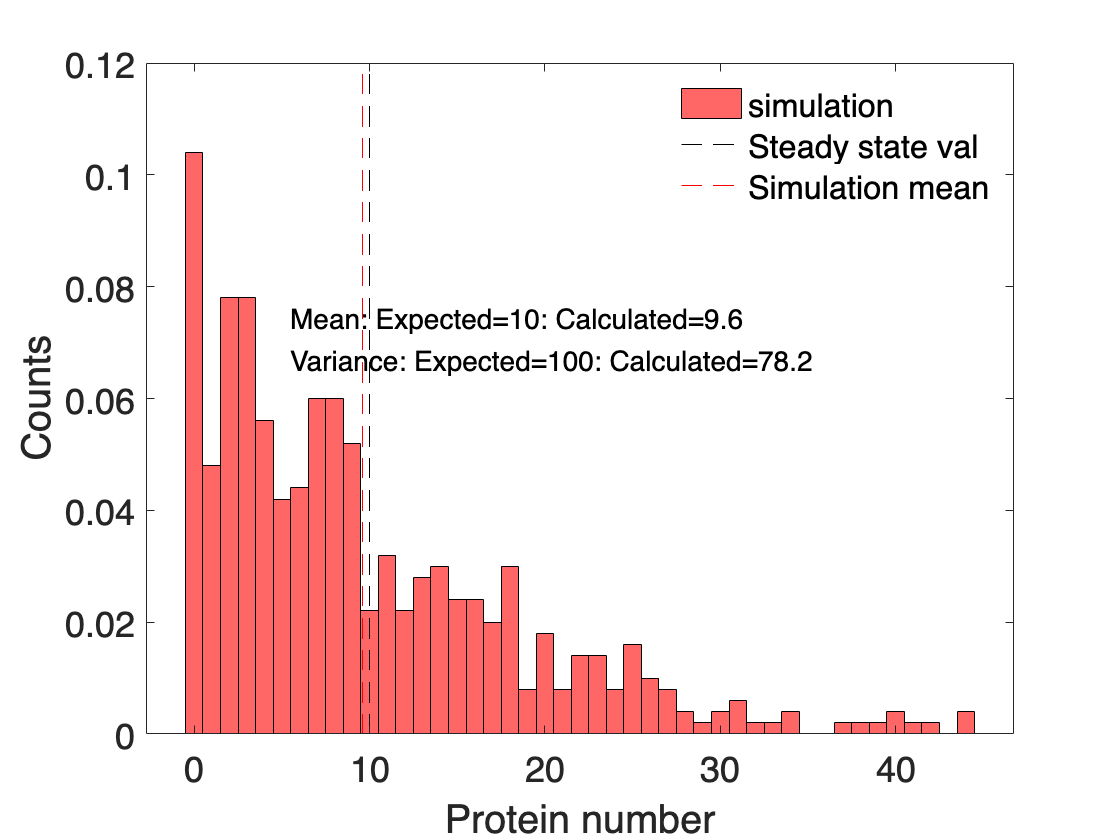

plot_statistics(p,P2)

[P2_mean_cal, P2_mean_expec, P2_var_cal, P2_var_expec] = display_statistics(p, P2);

Variance: Expected=100\n: Calculated=78.2489\nMean: Expected=10\n: Calculated=9.598\nCV: Expected=1\n: Calculated=0.92163

Increasing  $a$ even more leads to an skewed distribution as shown below:

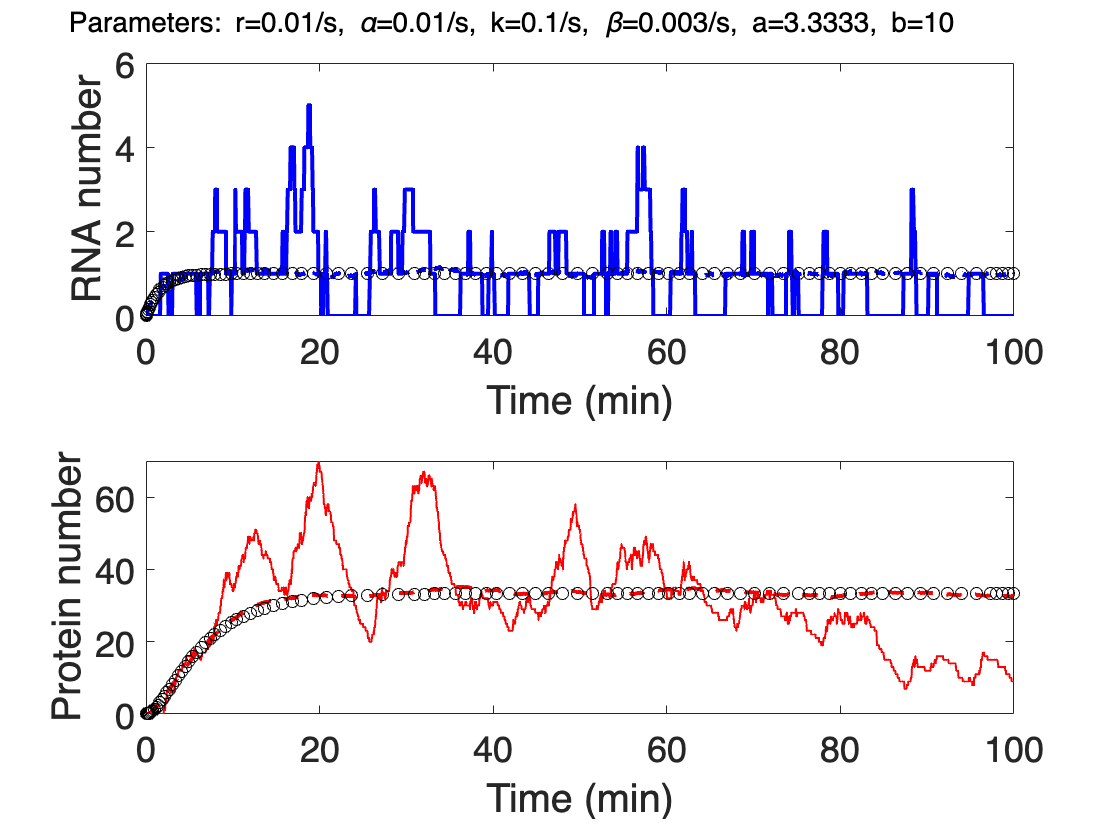

%%%%%%%%%%%%%%%%%%%% case 3
p.alpha=0.01;%%/s, RNA degredation rate
p.beta=0.003;%%/s, Protein degradation rate
p.r=0.01; %RNA production rate
p.k=0.1;%%/s, Protein Synthesis rate
p.a=p.r/p.beta;%%%% number of bursts per protein lifetime
p.b=p.k/p.alpha;%%%% number of protein in each burst

%Now simulate using monte carlo
p.startTime = 0;
p.endTime =  60*100; % in seconds
p.nrep = 500;  % number of replicate simulations
p.dt=0.1;
% Stochastic simulation
R0=0;
P0=0;

[T3,R3,P3]=RNAProtein_MonteCarlo(p,R0,P0);
plot_trace(p,T3,R3,P3)

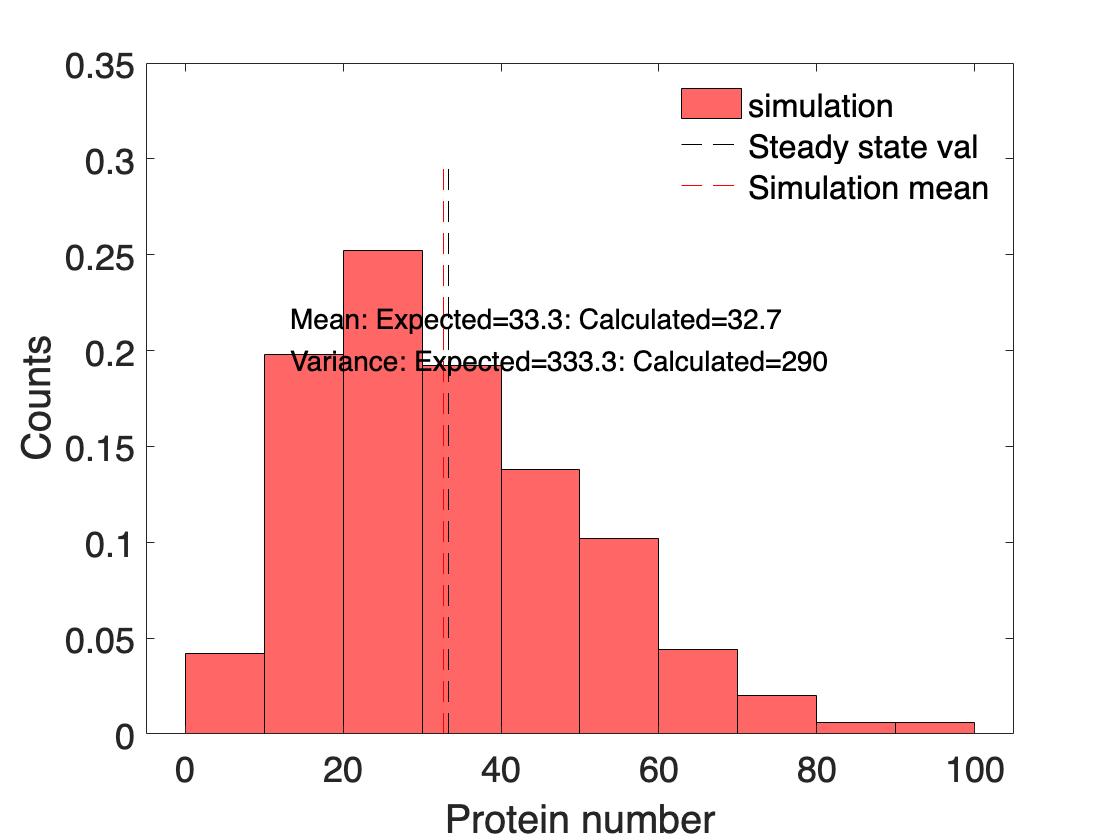

plot_statistics(p,P3)

[P3_mean_cal, P3_mean_expec, P3_var_cal, P3_var_expec] = display_statistics(p, P3);

Variance: Expected=333.3333\n: Calculated=290.0274\nMean: Expected=33.3333\n: Calculated=32.716\nCV: Expected=0.54772\n: Calculated=0.52055

%%%%%%%%%%%%%%%%%%%%%%%

Increasing  $a$ further the protein distribution becomes gaussian-like.

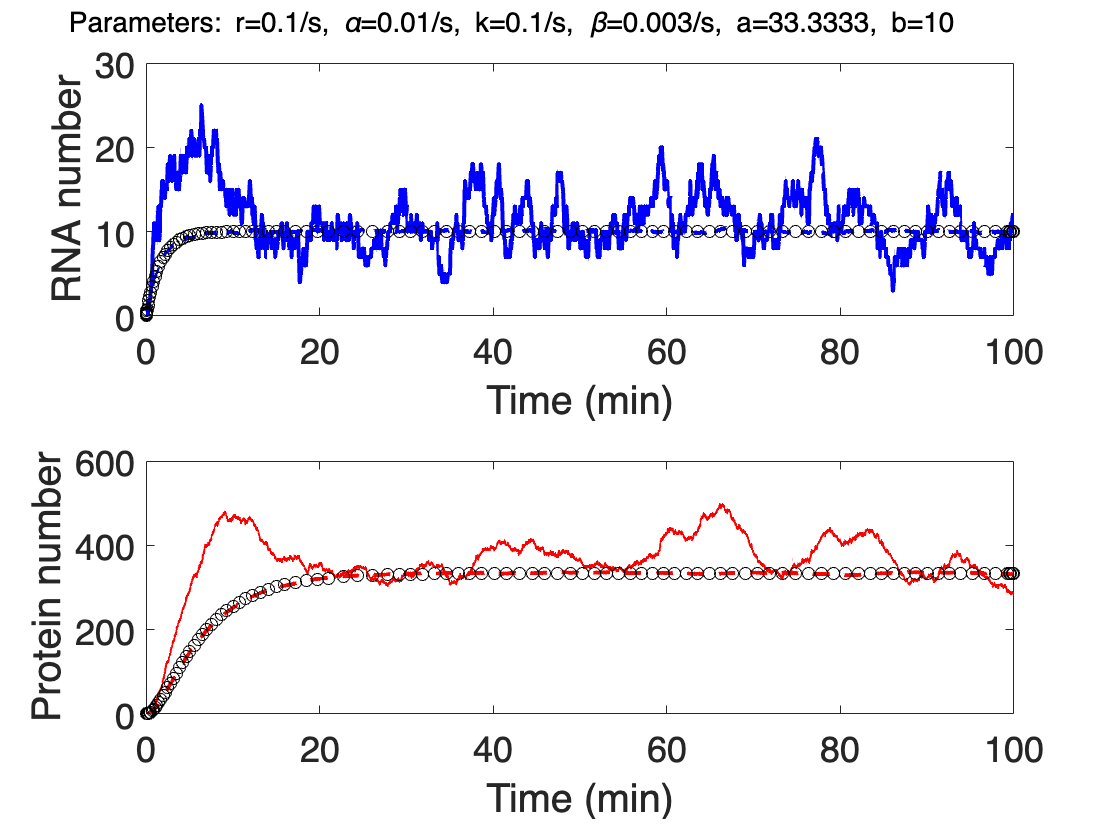

%%%%%%%%%%%%%%%%%%%%%%% case 4
tic
p.alpha=0.01;%%/s, RNA degredation rate
p.beta=0.003;%%/s, Protein degradation rate
p.r=0.1; %RNA production rate 
p.k=0.1;%%/s, Protein Synthesis rate 
p.a=p.r/p.beta;%%%% number of bursts per protein lifetime
p.b=p.k/p.alpha;%%%% number of protein in each burst
%Now simulate using monte carlo
p.startTime = 0;
p.endTime =  60*100; % in seconds
p.nrep = 500;  % number of replicate simulations
p.dt=0.01;%%%time steps
% Stochastic simulation
R0=0;
P0=0;

tic
[T4,R4,P4]=RNAProtein_MonteCarlo(p,R0,P0);
t_MonteCarlo=toc;
plot_trace(p,T4,R4,P4)

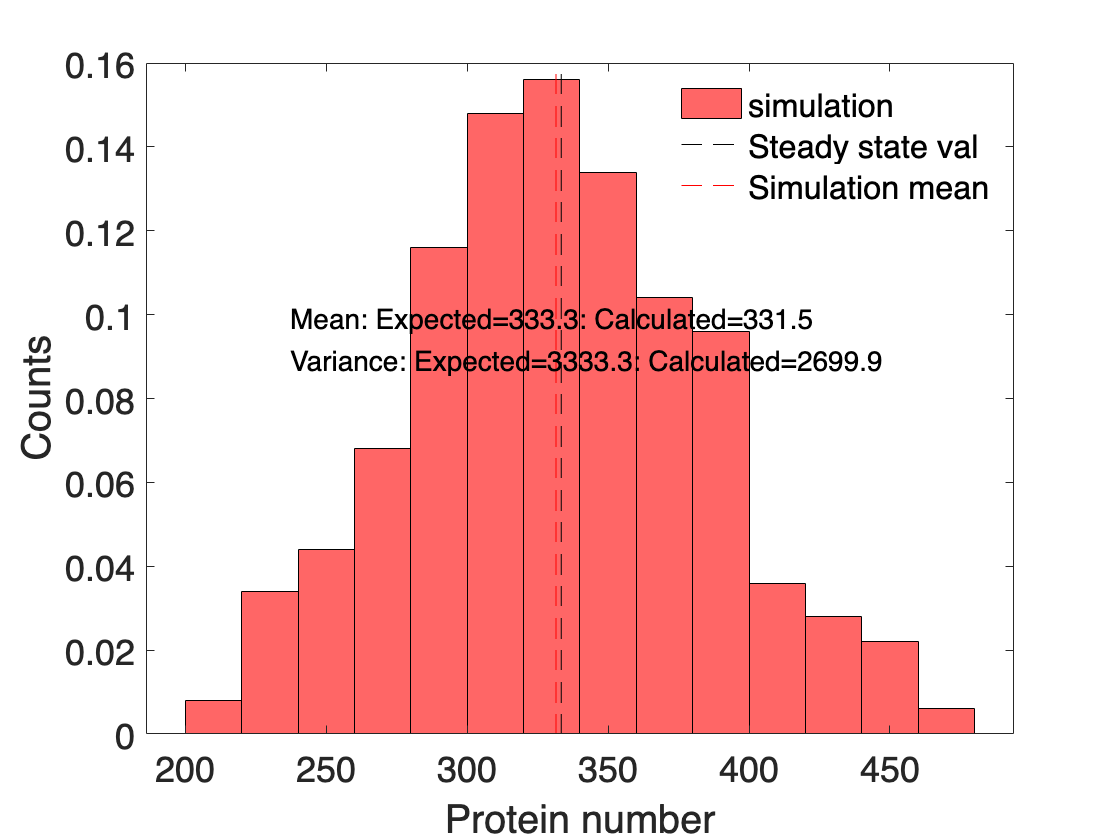

plot_statistics(p,P4)

[P4_mean_cal, P4_mean_expec, P4_var_cal, P4_var_expec] = display_statistics(p, P4);

Variance: Expected=3333.3333\n: Calculated=2699.9258\nMean: Expected=333.3333\n: Calculated=331.504\nCV: Expected=0.17321\n: Calculated=0.15674

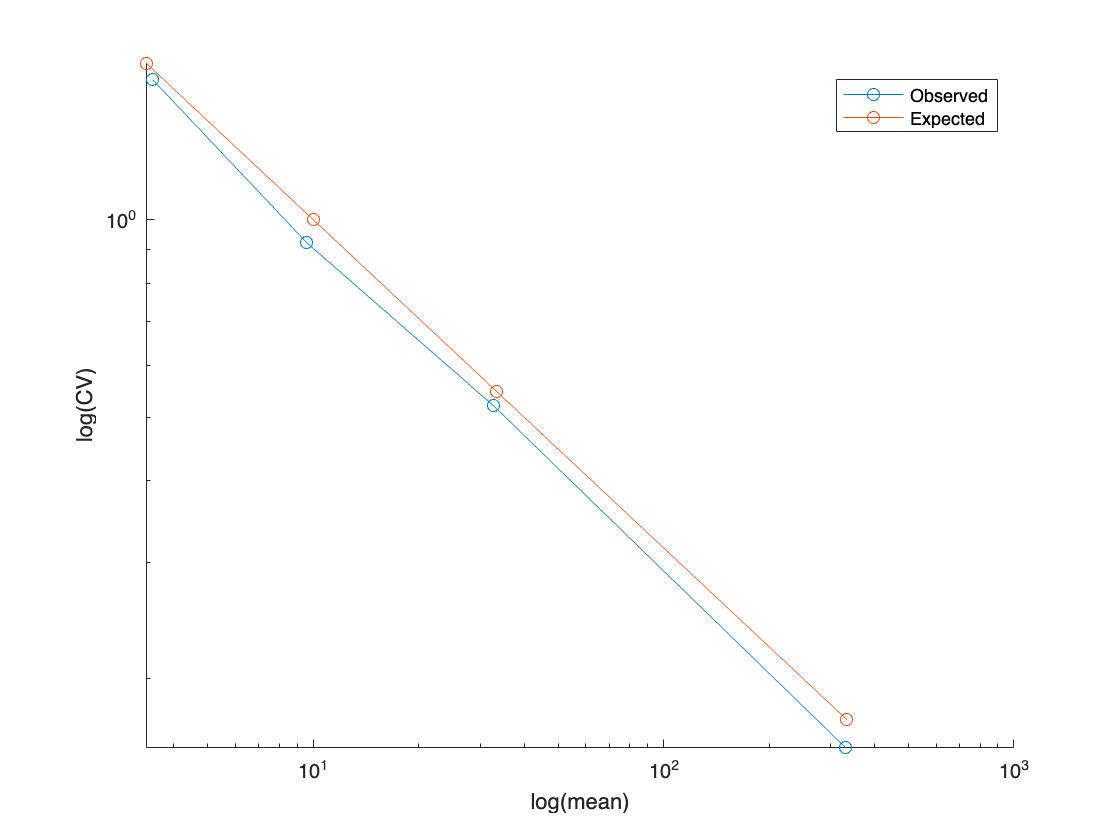

cvs_cal = [ ...
    sqrt(P1_var_cal)/P1_mean_cal; ...
    sqrt(P2_var_cal)/P2_mean_cal; ...
    sqrt(P3_var_cal)/P3_mean_cal; ...
    sqrt(P4_var_cal)/P4_mean_cal ...
];

cvs_expec = [ ...
    sqrt(P1_var_expec)/P1_mean_expec; ...
    sqrt(P2_var_expec)/P2_mean_expec; ...
    sqrt(P3_var_expec)/P3_mean_expec; ...
    sqrt(P4_var_expec)/P4_mean_expec ...
];

figure; hold on;
plot([P1_mean_cal; P2_mean_cal; P3_mean_cal; P4_mean_cal], cvs_cal, '-o');
plot([P1_mean_expec; P2_mean_expec; P3_mean_expec; P4_mean_expec], cvs_expec, '-o');
legend('Observed', 'Expected')
xlabel('log(mean)');
ylabel('log(CV)');
set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');

**Conclusions:**

- Check with different time intervals.

- How to improve the speed of this algorithm. One way to do it is: generate the random numbers in batches to make it faster.

- A better way to speed it up to use Gillespie algorithm.

**Gillespie Algorithm:**

To overcome the drawbacks of Monte-Carlo algorithm, we introduce the **Gillespie Algorithm** (Gillespie, 1977). In this algorithm, instead of iterating over each time step, we advance to the next time step only when a reaction is predicted to occur, making the algorithm much faster. Importantly, the value of $\Delta t$ is not a concern in this approach. We know from Eq(9) that the time to next reaction is exponentially distributed. We can transform  an uniform random number by setting

                                                                                                                    
$$\mathbb R_1=e^{-\tau \sum_i K_i}$$


taking log on both sides leads to the following:

                                                                                                            
$$\tau = -\frac{ln(\mathbb R_1)}{\sum_i ki}$$


We will use this formula to generate exponentially distributed reaction times.

Here is a pseudo code to simulate Gillespie algorithm (for detailed code see see the function called 'RNAProtein_Gillespie'):

If current time $t$ is less than the maximum simulation time ($$ T_{Max}$$), do the following:

- Generate two uniformly distributed random numbers $\mathbb R_1~\&~\mathbb R_2$ between 0 to 1.

- Compute  the time to next reaction by drawing an expenential random number as discussed earlier using $\tau=\frac{-ln(\mathbb R_1)}{\sum_{i} k_i}$.

- Choose the chemical reaction to execute as done in Monte-carlo method :

                                                                                        
$$\mathbb R_2>=\frac{1}{k_0}\sum_{i=1}^{j-1} k_i (t)~~\&~~\mathbb R_2<\frac{1}{k_0}\sum_{i=1}^{j} k_i(t)$$


            4.Advance the time by $\tau$.

Now let's do the previous simulation but using Gillespie algorithm.

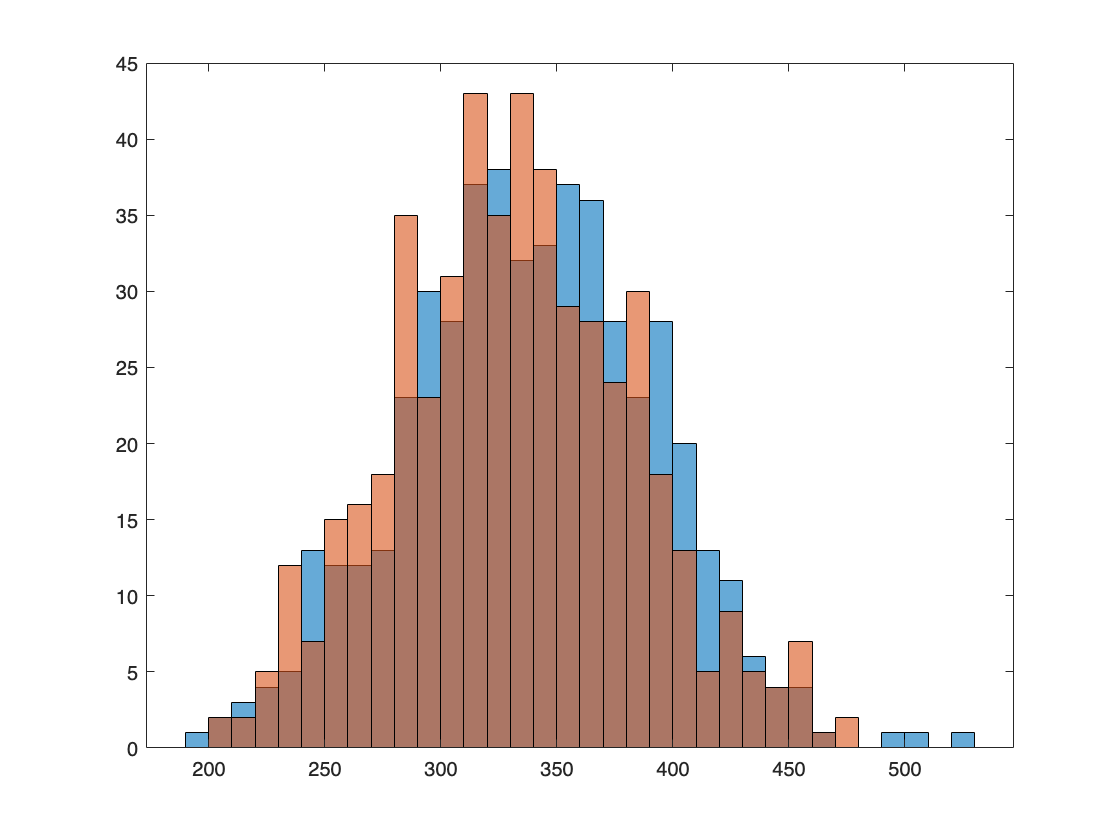

p.dtForOutput=0.1;%%%time interval for output storage
tic
[TG,RG,PG]=RNAProtein_Gillespie(p,R0,P0);
t_Gillespie=toc;

figure
histogram(PG(end,:),'BinWidth',10)
hold on
histogram(P4(end,:),'BinWidth',10)

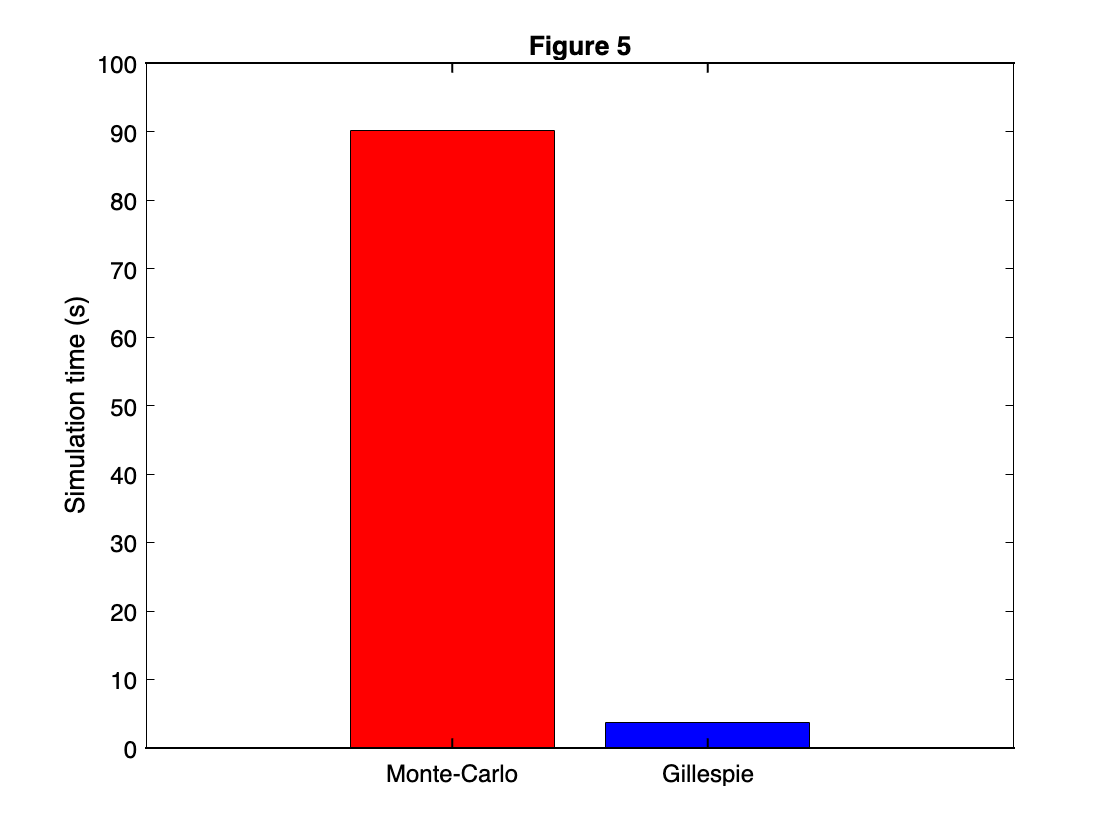


figure
bar(1,t_MonteCarlo,'FaceColor','r')
hold on
bar(2,t_Gillespie,'FaceColor','b')
xticks([1,2])
xticklabels({'Monte-Carlo','Gillespie'})
ylabel('Simulation time (s)')
box on
title('Figure 5')
set(gca,'FontName','Helvetica','FontSize',12,'GridAlpha',0.15,'color','w','xcolor','k','ycolor','k','LineWidth',1);

**Here is the function for Monte-Carlo Algorithm:**

%% monte-carlo for transcription and translation
%%%%%%%% Monte Carlo for DNA->RNA->Protein
%%%%%%%%                       |      |
%%%%%%%%                       V      V
%%%%%%%%                       0      0

%%%%%%%%%%%% The ODE's %%%%%%%%%%%%%
%     R'== r    -  alpha*R;
%     P'== k*R  -  beta*P;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% inputs:
%   p is the parameter set, user defines  
%                   p.r->RNA production rate 
%                   p.alpha->RNA degradation rate 
%                   p.k-> Protein Synthesis rate , 
%                   p.beta -> Proteain degradation rate
%                   p.startTime-> start time of simulation 
%                   p.endTime->end time of simulation
%                   p.nrep->number of simulation repeats
%                   p.dt->time steps
%   R0->initial copy number of RNA
%   P0->initial copy number of RNA

% outputs:
%    T: is the time column vector with timestep(=(endTime-startTimep)/dt) rows
%    R: array of size timestep X p.nrep contains the time series of RNA
%    P: array of size timestep X p.nrep contains the time series of protein
%   
%%example
% p.alpha=0.01;%%/s, RNA degredation rate
% p.beta=0.003;%%/s, Protein degradation rate
% p.r=0.001; %RNA production rate 
% p.k=0.1;%%/s, Protein Synthesis rate 

% 
% %Now simulate using monte carlo
% p.startTime = 0;
% p.endTime =  60*100; % in seconds
% p.nrep = 500;  % number of replicate simulations
% p.dt=0.1;
% % Set the initial values
% R0=0;
% P0=0;
% %%% run the monte carlo simulation
% [T1,R1,P1]=RNAProtein_MonteCarlo(p,R0,P0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function  [time,R,P]=RNAProtein_MonteCarlo(p,R0,P0)
%%%%% create the time vector with dt timesteps
time=(p.startTime:p.dt:p.endTime)';
%%%% arrays to store the RNA and Proteins
R=zeros(length(time),p.nrep);
P=zeros(length(time),p.nrep);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for rep=1:p.nrep %%%%%%%%%%%%%%% ensemble loop
    %%%% store initial values, this is the first time step
    R(1,rep)=R0;
    P(1,rep)=P0;
    for t=2:length(time) %%%%%%%%%%%%%%% go ovet each time step
        %%% calculate the total reaction rates
        total_reactionrate =sum([p.r , p.alpha*R(t-1,rep) ,p.k*R(t-1,rep) ,p.beta*P(t-1,rep)]);
        %%%%% calculate reaction prob. 
        reaction_prob=1-exp(-total_reactionrate*p.dt);
        %%% now we need a random number to check whether a reaction will
        %%% occur
        random1=rand;
        if random1<reaction_prob%%%%%% reaction happens if condition met
            %%Now we have to choose which reaction to execute
            random2=rand;
            %%% calculate reaction prob of individual reactions
            r1=p.r/total_reactionrate;
            r2=p.alpha*R(t-1,rep)/total_reactionrate;
            r3=p.k*R(t-1,rep)/total_reactionrate;
            r4=p.beta*P(t-1,rep)/total_reactionrate;

            if random2<r1
                R(t,rep)=R(t-1,rep)+1;%%%%% first possible reaction RNA synthesis
                P(t,rep)=P(t-1,rep);%%%% no change in Protein
            elseif random2>=r1 && random2<r1+r2
                R(t,rep)=R(t-1,rep)-1;%%%%% 2nd possible reaction RNA degredation
                P(t,rep)=P(t-1,rep);%%%% no change in Protein
            elseif random2>=r1+r2 && random2<r1+r2+r3
                R(t,rep)=R(t-1,rep);%%%% no change in RNA
                P(t,rep)=P(t-1,rep)+1;%%%%% 3rd possible reaction Protein synthesis
            else
                R(t,rep)=R(t-1,rep);%%%% no change in RNA
                P(t,rep)=P(t-1,rep)-1;%%%%% 4th possible reaction, Protein degradation
            end
        else%%%% no reaction takes place, keep current values as previous
            R(t,rep)=R(t-1,rep);
            P(t,rep)=P(t-1,rep);
        end

    end
end
end

**Here is the function for Gillespie Algorithm:**


%% Gillespie algorithm for transcription and translation
%%%%%%%% Monte Carlo for DNA->RNA->Protein
%%%%%%%%                       |      |
%%%%%%%%                       V      V
%%%%%%%%                       0      0

%%%%%%%%%%%% The ODE's %%%%%%%%%%%%%
%     R'== r    -  alpha*R;
%     P'== k*R  -  beta*P;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% inputs:
%   p is the parameter set, user defines  
%                   p.r->RNA production rate 
%                   p.alpha->RNA degradation rate 
%                   p.k-> Protein Synthesis rate , 
%                   p.beta -> Proteain degradation rate
%                   p.startTime-> start time of simulation 
%                   p.endTime->end time of simulation
%                   p.nrep->number of simulation repeats
%                   p.dtForOutput->time interval for output values
%   R0->initial copy number of RNA
%   P0->initial copy number of Protein

% outputs:
%    T: is the time column vector with timestep(=(endTime-startTimep)/dt) rows
%    R: array of size timestep X p.nrep contains the time series of RNA
%    P: array of size timestep X p.nrep contains the time series of protein
%   
%%example
% p.alpha=0.01;%%/s, RNA degredation rate
% p.beta=0.003;%%/s, Protein degradation rate
% p.r=0.001; %RNA production rate 
% p.k=0.1;%%/s, Protein Synthesis rate 

% %Now simulate using Gillespie algorithm
% p.startTime = 0;
% p.endTime =  60*100; % in seconds
% p.nrep = 500;  % number of replicate simulations
% p.dtForOutput=0.1;
% % Set the initial values
% R0=0;
% P0=0;
% %%% run the Gillespie simulation
% [T,R,P]=RNAProtein_Gillespie(p,R0,P0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function  [T,R,P]=RNAProtein_Gillespie(p,R0,P0)
% create arrays for output
R=zeros((p.endTime-p.startTime)/p.dtForOutput,p.nrep);%%%% arrays to store RNA number
P=zeros((p.endTime-p.startTime)/p.dtForOutput,p.nrep);%%%% arrays to store Proteins number
T=(p.startTime:p.dtForOutput:p.endTime)';%%% The time vector with an interval p.dtForOutput
maxtime_indx=length(T);
%%%% generate another random number in batches for faster simulation
Max_random=10000000;
rindx=1;
Random=rand(Max_random,2);
%%%%%%%%%%%%%%%%% Now Start the Simulation %%%%%%%%%%%%%%%%%%%%%%%
for rep=1:p.nrep %%%%%%%%%%%%%%% ensemble loop
    %%%% store initial values, this is the first time step
    ind_current=1;%%%%% index of current time step;
    R_current=R0;%%%%% initial number of RNA
    P_current=P0;%%%%% iinitial number of proteins
    time=p.startTime;%%%%% initialize time at start time
    while time<=p.endTime %%%%%%%%%%%%%%% go ovet each time step
        %%%%%%%%%%% if all random numbers are exhausted repopulate it again
        if rindx>Max_random
            Random=rand(Max_random,2);
            rindx=1;
        end
        %%% calculate the total reaction rates
        reaction_rates=[p.r,p.alpha*R_current,p.k*R_current,p.beta*P_current];
        total_reactionrate = sum(reaction_rates);
        %%%%% calculate time to next reaction
            random1=Random(rindx,1);
            tau=-log(random1)/total_reactionrate;  %waiting time for the next reaction 
            t_next=time+tau;%%%%%%%% time of the next reaction
            %%%%%%%%%%%%%%%%% Some house keeping, populate staorage until the next reaction
            ind_closest=round(t_next/p.dtForOutput)+1;%% find closest index in the time vector        
            ind_next=min([maxtime_indx,ind_closest]);%% limit the time to maximum simulation time
            %%%%%%%%%%%%%% store previous values until the next reaction
            for ind=ind_current:ind_next
                R(ind,rep)=R_current;%%%% 
                P(ind,rep)=P_current;%%%%% 
            end
            %%%%%%%%%%%%%%%%%%%% Now we have to choose which reaction to execute          
            %%%%%%%%%%%%%%%%%%%  calculate reaction prob of individual reactions
            reaction_prob=reaction_rates./total_reactionrate;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            random2=Random(rindx,2);
            %%%%%%%%%%%%%%%%%%%%%%% fire the next reaction based on probabilities and then update RNA/protein numbers
            if random2<reaction_prob(1)                         
                R_current=R_current+1;%%%%% first possible reaction RNA synthesis    
            elseif random2>=reaction_prob(1) && random2<reaction_prob(1)+reaction_prob(2)            
                R_current=R_current-1;%%%%%%% 2nd possible reaction RNA degredation         
            elseif random2>=reaction_prob(1)+reaction_prob(2) && random2<reaction_prob(1)+reaction_prob(2)+ reaction_prob(3)                    
                P_current=P_current+1;%%%% 3rd possible reaction Protein synthesis
            else
                P_current=P_current-1;%%%%% 4th possible reaction, Protein degradation
            end   
            %%%%%%%%%%%%%% update time 
        time=t_next;%%% Update time to the next reaction time
        ind_current=ind_next+1;%%% Update current time index
        rindx=rindx+1;%%% Update index for random number
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end
end

**Some more utility plotting functions:**



%%%% Plotting functions %%%%%%%%%%%%%%%%%%%%%%%
function plot_trace(p,T,R,P)
Z0=[0;...
    0];

dZdt=@(Z,p)[p.r-p.alpha*Z(1);...
    p.k*Z(1)-p.beta*Z(2)];
tspan=[p.startTime p.endTime];
[t,Z] = ode45(@(t,Z) dZdt(Z,p),tspan,Z0);

R_SS=p.r/p.alpha;
P_SS=p.k*p.r/(p.alpha*p.beta);
figure
subplot(2,1,1)
title('RNA Trace')
plot(T./60,R(:,1),'-b','LineWidth',2)
hold on
plot(T./60,mean(R,2),'--b','LineWidth',2)

plot(t./60,Z(:,1),'ok')
xl = get(gca, 'XLim');
%plot(xl,R_SS*ones(size(xl)),'--b','LineWidth',2)

xlabel('Time (min)')
ylabel('RNA number')
box on
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);

subplot(2,1,2)
plot(T./60,P(:,1),'-r','LineWidth',1)
hold on
plot(T./60,mean(P,2),'--r','LineWidth',2)
xl = get(gca, 'XLim');
%plot(xl,P_SS*ones(size(xl)),'--r','LineWidth',2)
plot(t./60,Z(:,2),'ok')
xlabel('Time (min)')
ylabel('Protein number')
box on

set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);
String=strcat('Parameters: r=',num2str(p.r),'/s, \alpha=',num2str(p.alpha),'/s, k=',num2str(p.k),'/s, \beta=',num2str(p.beta),...
    '/s, a=',num2str(p.a),', b=',num2str(p.b));
annotation('textbox',[.05 .9 .95 .1],'String',String,'EdgeColor','none','FontSize',14)
end

function plot_statistics(p,P)
R_SS=p.r/p.alpha;
P_SS=p.k*p.r/(p.alpha*p.beta);
figure
val=reshape(P(end,:),[],1);
title('Protein distribution')
histogram(val,'FaceColor','r','Normalization','probability')
hold on
ylabel('Counts')
xlabel('Protein number')
yl = get(gca, 'YLim');
xl = get(gca, 'XLim');
plot(P_SS*ones(size(yl)),yl,'--k')
plot(mean(val)*ones(size(yl)),yl,'--r')
vexpec=p.a*p.b^2;
vcal=var(val);

legend('simulation','Steady state val','Simulation mean')
legend boxoff  
box on
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);
String1=strcat('Variance: Expected=',num2str(round(vexpec,1)),': Calculated=',num2str(round(vcal,1)));
String2=strcat('Mean: Expected=',num2str(round(P_SS,1)),': Calculated=',num2str(round(mean(val),1)));
annotation('textbox',[.25 .5 .75 .1],'String',String1,'EdgeColor','none','FontSize',14)
annotation('textbox',[.25 .55 .75 .1],'String',String2,'EdgeColor','none','FontSize',14)
end


% function to print out statistics.
function [mean_cal, mean_expec, var_cal, var_expec] = display_statistics(p, P)

    R_SS = p.r/p.alpha;
    P_SS = p.k*p.r/(p.alpha*p.beta);
    val = reshape(P(end,:),[],1);
    
    mean_cal = mean(val);
    mean_expec = P_SS;
    var_cal = var(val);
    var_expec = p.a*p.b^2;
    cv_cal = sqrt(var_cal)/mean_cal;
    cv_expec = sqrt(var_expec)/P_SS;

    fprintf("%s", strcat('Variance: Expected=',num2str(var_expec),'\n: Calculated=',num2str(var_cal)));
    fprintf("%s", strcat('\nMean: Expected=',num2str(mean_expec),'\n: Calculated=',num2str(mean_cal)));
    fprintf("%s", strcat('\nCV: Expected=',num2str(cv_expec),'\n: Calculated=',num2str(cv_cal)));
end